unitTrain = nonzeros(experiment.Units.good.times(6,:))

unitTrain = unitTrain/30000;

expLength = length(experiment.sound.full)/30000

spikeVec = getSDFBinned(unitTrain,expLength);

spikVecSec = spikeVec*expLength

alumVec = intersect(experiment.conditionVector.aluminum,timeDS);

whisking =  experiment.Whisking.smoothed(1:697699)/1000

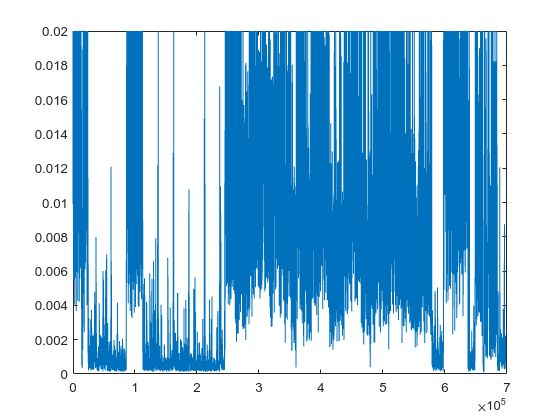

figure; plot(whisking)

whisking(whisking>0.02) = 0.02

whisking =     0.0158    0.0163    0.0161    0.0155    0.0155    0.0158    0.0161    0.0160    0.0154    0.0152    0.0153    0.0154    0.0153    0.0150    0.0148    0.0149    0.0152    0.0154    0.0155    0.0155    0.0154    0.0153    0.0152    0.0152    0.0154    0.0150    0.0146    0.0143    0.0143    0.0140    0.0133    0.0128    0.0129    0.0134    0.0131    0.0123    0.0118    0.0118    0.0124    0.0130    0.0130    0.0124    0.0121    0.0124    0.0131    0.0134    0.0133    0.0128    0.0128    0.0133


k = 0.025

k = 0.0250

figure
plot(timeDS,a.soundSmoothed/1000-0.05,'Color',[102/255,0,102/255])
hold on
ii = [6,28];
cColor = {[210/255,37/255,0],[22/255,42/255,98/255]}

cColor = 1×2 cell array
    {[0.8235 0.1451 0]}    {[0.0863 0.1647 0.3843]}


for i = 1:2
    g = find(a.raster(ii(i),:) ==1);
%     scatter(g/1000,ones(1,length(g))*k*i+0.2,[],cColor{i},'|')
    plot(timeDS,a.units(ii(i),:)+i*k+0.15*i+0.025,'Color',cColor{i})
    
end
plot(timeDS,(runningDS/500)-0.4,'color',[35/255,53/255,56/255])
plot(experiment.Cams.whisking.csv_aligned_frames/30000,whisking*5-0.2,'color',colorBen.green)
hold on
xline(ib/1000)
line([500,560],[0.5 0.5],'LineWidth',1.5,'color','k')
xlim([500 1400])
line([500,500],[0.5 0.55],'LineWidth',1.5,'color','k')
line([500,500],[-0.36 -0.4],'LineWidth',1.5,'color','k')
labels = {'Al','At','FW'}

labels = 1×3 cell array
    {'Al'}    {'At'}    {'FW'}


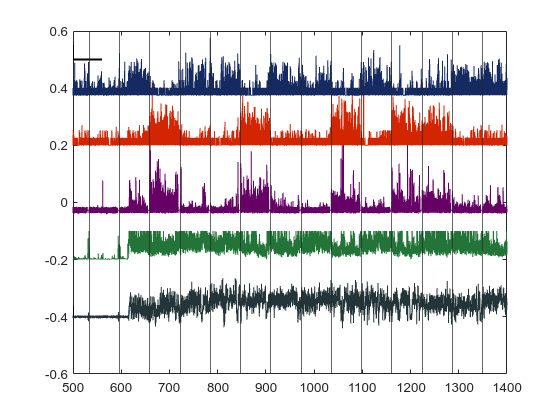

for kk = 1:length(artifactDS)
    text(ib(kk)/1000,0.8,labels(experiment.Conditions.condition_classification(kk)))
end

b = a.soundSmoothed

for j = 1:length(ib)
    startC = ib(j) - 4000;
    a.soundSmoothed(startC:ib(j)) = median(a.soundSmoothed);
end

a.soundSmoothed(a.soundSmoothed > 270) = 270

plot(a.soundSmoothed,'Color',[102/255,0,102/255])

runningDS = resample(experiment.running,1000,30000)

runningDS(runningDS > 100 | runningDS < -20) = mean(runningDS)

figure; plot(runningDS,'color',[252/255,166/255,109/255])

hold on
plot(runningDS-10,'color',[230/255,123/255,87/255])
plot(runningDS-20,'color',[230/255,165/255,87/255])

changeCon = intersect(a.timeDS,experiment.Conditions.all_changes)

bin_edges = [0:0.001:expLength+0.001];
unitBinned = histcounts(unitTrain,bin_edges);

[gg,ii] = sort(experiment.Units.conditionsStats.FRVector(:,1),'descend')


a.raster(a.raster > 1) == 1;

for i = ii
    ii
end

timeDS = [1:length(runningDS)]/1000

artifact = double(experiment.Conditions.all_changes)
artifactDS = []

for chCon = 1:length(artifact)
    [~,tempA] = min(abs(artifact(chCon) - a.timeDS))
    artifactDS(chCon) = a.timeDS(tempA);
end


[hh,ia,ib] = intersect(artifactDS,a.timeDS)